# simulated ecg

figureを作成

f1 = figure('Name','SAMPLE 01');
f2 = figure('Name','SAMPLE 02');
f3 = figure('Name','SAMPLE 03');
f4 = figure('Name','SAMPLE 04');
f5 = figure('Name','SAMPLE 05');
f6 = figure('Name','SAMPLE 06');
f7 = figure('Name','SAMPLE 07');
f8 = figure('Name','SAMPLE 08');
f9 = figure('Name','SAMPLE 09');
fX = figure('Name','SAMPLE 10');

2秒分(1000samples)のプロットを比較

xa = linspace(1,30000,30000);
xp = linspace(1,1000,1000);

同時samplingなのでdataをalignする必要は無い

yfa=zeros(10, 30000);
yaa=zeros(10, 30000);
for c=1:30000
    yfa(1,c) = humfas01(c);
    yaa(1,c) = humagp01(c);
    yfa(2,c) = humfas02(c);
    yaa(2,c) = humagp02(c);
    yfa(3,c) = humfas03(c);
    yaa(3,c) = humagp03(c);
    yfa(4,c) = humfas04(c);
    yaa(4,c) = humagp04(c);
    yfa(5,c) = humfas05(c);
    yaa(5,c) = humagp05(c);
    yfa(6,c) = humfas06(c);
    yaa(6,c) = humagp06(c);
    yfa(7,c) = humfas07(c);
    yaa(7,c) = humagp07(c);
    yfa(8,c) = humfas08(c);
    yaa(8,c) = humagp08(c);
    yfa(9,c) = humfas09(c);
    yaa(9,c) = humagp09(c);
    yfa(10,c) = humfas10(c);
    yaa(10,c) = humagp10(c);
end

yfp=zeros(1000);
yap=zeros(1000);
b = 10000;
for c=1:1000
    yfp(1,c) = humfas01(b+c);
    yap(1,c) = humagp01(b+c);
    yfp(2,c) = humfas02(b+c);
    yap(2,c) = humagp02(b+c);
    yfp(3,c) = humfas03(b+c);
    yap(3,c) = humagp03(b+c);
    yfp(4,c) = humfas04(b+c);
    yap(4,c) = humagp04(b+c);
    yfp(5,c) = humfas05(b+c);
    yap(5,c) = humagp05(b+c);
    yfp(6,c) = humfas06(b+c);
    yap(6,c) = humagp06(b+c);
    yfp(7,c) = humfas07(b+c);
    yap(7,c) = humagp07(b+c);
    yfp(8,c) = humfas08(b+c);
    yap(8,c) = humagp08(b+c);
    yfp(9,c) = humfas09(b+c);
    yap(9,c) = humagp09(b+c);
    yfp(10,c) = humfas10(b+c);
    yap(10,c) = humagp10(b+c);
end

#### レベルの違いを吸収するために正規化

all

for c= 1:10
    yfa(c)=normalize(yfa(c));
    yfp(c)=normalize(yfp(c));
end

#### plot

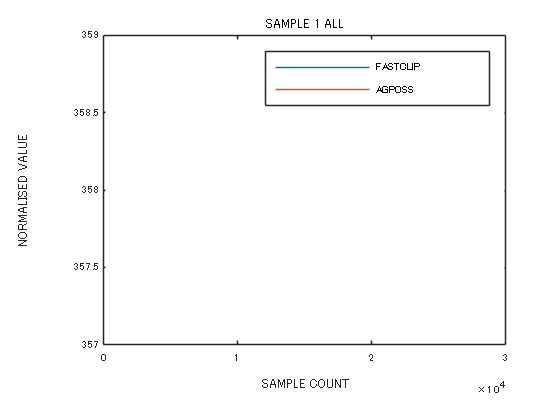

texttitle = "SAMPLE 1 ALL"

texttitle = "SAMPLE 2 ALL"

texttitle = "SAMPLE 3 ALL"

texttitle = "SAMPLE 4 ALL"

texttitle = "SAMPLE 5 ALL"

texttitle = "SAMPLE 6 ALL"

texttitle = "SAMPLE 7 ALL"

texttitle = "SAMPLE 8 ALL"

texttitle = "SAMPLE 9 ALL"

texttitle = "SAMPLE 10 ALL"

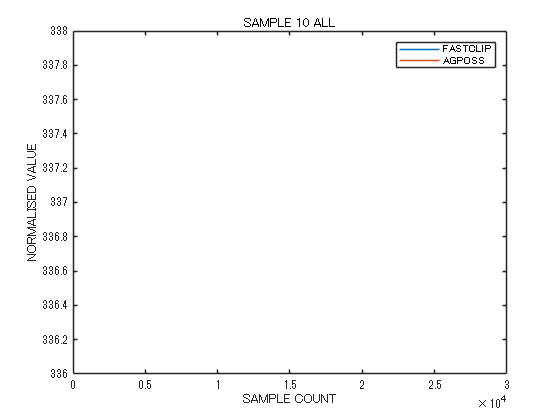

for c=1:10
    figure(f1);
    plot(xa, yfa(c), xa, yaa(c))
    legend("FASTCLIP", "AGPOSS");
    xlabel("SAMPLE COUNT");
    ylabel("NORMALISED VALUE");
    texttitle = "SAMPLE " + c + " ALL";
    title(texttitle);
end

figure(f2);
plot(xa, yf02a, xa, ya02a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 02 ALL");
figure(f3);
plot(xa, yf03a, xa, ya03a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 03 ALL");
figure(f4);
plot(xa, yf04a, xa, ya04a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 04 ALL");
figure(f5);
plot(xa, yf05a, xa, ya05a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 05 ALL");
figure(f6);
plot(xa, yf06a, xa, ya06a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 06 ALL");
figure(f7);
plot(xa, yf07a, xa, ya07a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 07 ALL");
figure(f8);
plot(xa, yf08a, xa, ya08a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 08 ALL");
figure(f9);
plot(xa, yf09a, xa, ya09a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 09 ALL");
figure(fX);
plot(xa, yf10a, xa, ya10a)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 10 ALL");

#### partial

figure(f1);
plot(xp, yf01p, xp, ya01p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 01 PARTIAL");
figure(f2);
plot(xp, yf02p, xp, ya02p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 02 PARTIAL");
figure(f3);
plot(xp, yf03p, xp, ya03p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 03 PARTIAL");
figure(f4);
plot(xp, yf04p, xp, ya04p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 04 PARTIAL");
figure(f5);
plot(xp, yf05p, xp, ya05p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 05 PARTIAL");
figure(f6);
plot(xp, yf06p, xp, ya06p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 06 PARTIAL");
figure(f7);
plot(xp, yf07p, xp, ya07p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 07 PARTIAL");
figure(f8);
plot(xp, yf08p, xp, ya08p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 08 PARTIAL");
figure(f9);
plot(xp, yf09p, xp, ya09p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 09 PARTIAL");
figure(fX);
plot(xp, yf10p, xp, ya10p)
legend("FASTCLIP", "AGPOSS");
xlabel("SAMPLE COUNT");
ylabel("NORMALISED VALUE");
title("SAMPLE 10 PARTIAL");

**correlation coefficients**

**all**

1

cor_a(1) = corrcoef(yf01a,ya01a)

2

cor_a(1) = corrcoef(yf02a,ya02a)

3

cor03a = corrcoef(yf03a,ya03a)

4

cor04a = corrcoef(yf04a,ya04a)

5

cor05a = corrcoef(yf05a,ya05a)

6

cor06a = corrcoef(yf06a,ya06a)

7

cor07a = corrcoef(yf07a,ya07a)

8

cor08a = corrcoef(yf08a,ya08a)

9

cor09a = corrcoef(yf09a,ya09a)

10

cor10a = corrcoef(yf10a,ya10a)

**partial**

1

cor01p = corrcoef(yf01p,ya01p);
cor01p = cor01p(1,2)

2

cor02p = corrcoef(yf02p,ya02p)
cor02p = cor02p(1,2)

3

cor03p = corrcoef(yf03p,ya03p)
cor02p = cor02p(1,2)

4

cor04p = corrcoef(yf04p,ya04p)

5

cor05p = corrcoef(yf05p,ya05p)

6

cor06p = corrcoef(yf06p,ya06p)

7

cor07p = corrcoef(yf07p,ya07p)

8

cor08p = corrcoef(yf08p,ya08p)

9

cor09p = corrcoef(yf09p,ya09p)

10

cor10p = corrcoef(yf10p,ya10p)